2. Sa se aproximeze functia $f(x)=x^2 sin(x)$ pe intervalul $[-2\pi, 2\pi]$.

a. Folosind Spline-uri de Boor cu noduri echidistante, respectiv noduri Cebisev de speta a II-a, n=12.

b. Folosind metoda (discreta) celor mai mici patrate si noduri echidistante, n=11.

In ambele cazuri, reprezentati grafic functia si aproximarea acesteia.

Solutie:

a.

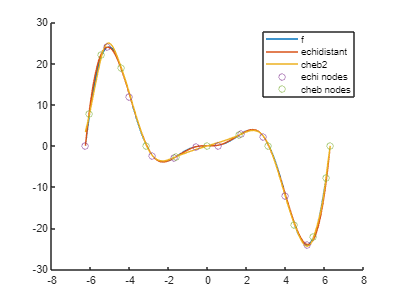

echi_nodes = linspace(-2*pi, 2*pi, 12);
chb2_nodes =  sort(2*pi * cos((0:11)*pi/12));


f = @(x) x.*x.*sin(x);

[ea, eb, ec, ed] = Splinecubic(echi_nodes, f(echi_nodes), 3);
[ca, cb, cc, cd] = Splinecubic(chb2_nodes, f(chb2_nodes), 3);

t = linspace(-2*pi, 2*pi);
y = f(t);
ey = valspline(echi_nodes, ea, eb, ec, ed, t);
cy = valspline(chb2_nodes, ca, cb, cc, cd, t);

clf; hold on;

plot(t, y)
plot(t, ey)
plot(t, cy)
scatter(echi_nodes, f(echi_nodes))
scatter(chb2_nodes, f(chb2_nodes))

legend("f","echidistant","cheb2","echi nodes", "cheb nodes")
ylim([-30,30])

hold off;

b.

phi = @(x)[ones(1, length(x)); x; x.^2; x.^3; x.^4; x.^5;x.^6;x.^7;x.^8;x.^9;x.^10];
x=linspace(-2*pi,2*pi,11)

x =    -6.2832   -5.0265   -3.7699   -2.5133   -1.2566         0    1.2566    2.5133    3.7699    5.0265    6.2832


y = f(x)

y =     0.0000   24.0296    8.3537   -3.7128   -1.5018         0    1.5018    3.7128   -8.3537  -24.0296   -0.0000


xx = linspace(-2*pi,2*pi, 100)

xx =    -6.2832   -6.1563   -6.0293   -5.9024   -5.7755   -5.6485   -5.5216   -5.3947   -5.2677   -5.1408   -5.0139   -4.8869   -4.7600   -4.6331   -4.5061   -4.3792   -4.2523   -4.1253   -3.9984   -3.8715   -3.7445   -3.6176   -3.4907   -3.3637   -3.2368   -3.1099   -2.9829   -2.8560   -2.7291   -2.6021   -2.4752   -2.3483   -2.2213   -2.0944   -1.9675   -1.8405   -1.7136   -1.5867   -1.4597   -1.3328   -1.2059   -1.0789   -0.9520   -0.8251   -0.6981   -0.5712   -0.4443   -0.3173   -0.1904   -0.0635


yy = least_squares_approx(x, y, phi, xx)

yy =     0.0000    2.1047    5.1680    8.6758   12.2379   15.5687   18.4698   20.8144   22.5340   23.6067   24.0460   23.8929   23.2075   22.0630   20.5397   18.7212   16.6902   14.5260   12.3020   10.0843    7.9306    5.8895    4.0001    2.2926    0.7877   -0.5019   -1.5714   -2.4229   -3.0645   -3.5094   -3.7746   -3.8804   -3.8490   -3.7038   -3.4687   -3.1671   -2.8210   -2.4511   -2.0757   -1.7105   -1.3685   -1.0596   -0.7907   -0.5655   -0.3849   -0.2472   -0.1481   -0.0813   -0.0387   -0.0112


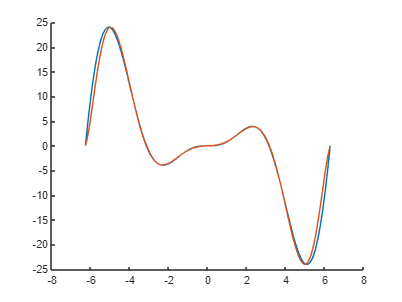

clf; hold on;
plot(xx, f(xx))
plot(xx, yy)
hold off;

function [a,b,c,d]=Splinecubic(x,f,tip,der)
%SPLINECUBIC - determina coeficientii spline-ului cubic
%x - abscisele
%f - ordonatele
%tip - 0 complet
% 1 cu derivate secunde
% 2 natural
% 3 not a knot (deBoor)
%der - informatii despre derivate
% [f’(a),f’(b)] pentru tipul 0
% [f’’(a), f’’(b)] pentru tipul 1
    if (nargin<4) || (tip==2) 
        der=[0,0]; 
    end
    n=length(x);
    %sortare noduri
    if any(diff(x)<0)
        [x,ind]=sort(x); 
    else 
        ind=1:n; 
    end
    y=f(ind); x=x(:); y=y(:);
    %obtin ecuatiile 2 ... n-1
    dx=diff(x); ddiv=diff(y)./dx;
    ds=dx(1:end-1); dd=dx(2:end);
    dp=2*(ds+dd);
    md=3*(dd.*ddiv(1:end-1)+ds.*ddiv(2:end));
    %tratare diferentiata tip - ecuatiile 1,n
    switch tip
        case 0 %complet
            dp1=1; dpn=1; vd1=0; vdn=0;
            md1=der(1); mdn=der(2);
        case {1, 2} %d2 si natural        
            dp1=2; dpn=2; vd1=1; vdn=1;
            md1=3*ddiv(1)-0.5*dx(1)*der(1);
            mdn=3*ddiv(end)+0.5*dx(end)*der(2);
        case 3 %deBoor
            x31=x(3)-x(1);xn=x(n)-x(n-2);
            dp1=dx(2); dpn=dx(end-1);
            vd1=x31; vdn=xn;
            md1=((dx(1)+2*x31)*dx(2)*ddiv(1)+dx(1)^2*ddiv(2))/x31;
            mdn=(dx(end)^2*ddiv(end-1)+(2*xn+dx(end))*dx(end-1)*...
            ddiv(end))/xn;
    end
    %construiesc sistemul rar
    dp=[dp1;dp;dpn]; dp1=[0;vd1;dd];
    dm1=[ds;vdn;0]; md=[md1;md;mdn];
    A=spdiags([dm1,dp,dp1],-1:1,n,n);
    m=A \ md;
    d=y(1:end-1);
    c=m(1:end-1);
    a=[(m(2:end)+m(1:end-1)-2*ddiv)./(dx.^2)];
    b=[(ddiv-m(1:end-1))./dx-dx.*a];
end

function z= valspline(x,a,b,c,d,t)
%evaluare spline
%apel z=valspline(x,a,b,c,d,t)
%z - valorile
%t - punctele in care se face evaluare
%x - nodurile
%a,b,c,d - coeficientii
    n=length(x);
    x=x(:); t=t(:);
    k = ones(size(t));
    for j = 2:n-1
        k(x(j) <= t) = j;
    end
    % Evaluare interpolant
    s = t - x(k);
    z = d(k) + s.*(c(k) + s.*(b(k) + s.*a(k)));
end

function res = least_squares_approx(x, y, functions, points)    
    phi = functions(x);
    phi_approx = functions(points);    
    
    n = length(x);
    [n, ~] = size(phi);
    
    % A = Z^T * Z ; B = Z^T * y ; unde Z^T e phi
    for i = 1 : n
        for j = 1 : n
            A(i, j) = phi(i, :) * transpose(phi(j, :));
        end
        B(i, 1) = phi(i, :) * transpose(y);
    end
       
    % A * a = B
    a = linsolve(A, B);    
    
    res = transpose(a) * phi_approx;
end
